# Shape descriptors. Fourier descriptors. - SS, lab 9

## Exercise 1

The image containing the three geometric figures is the image shown below

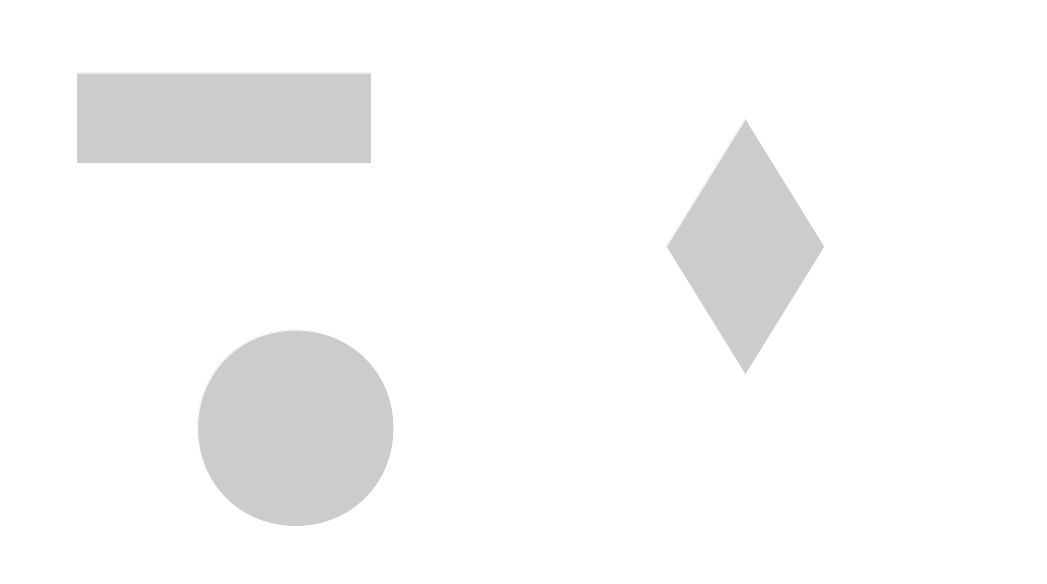

After boundary extraction, we have passed each of the objects of the above image to a function that calculates the Fourier series descriptors.

**After varying the number of Fourier coefficients, we observe that a larger number of coefficients means a more accurate representation of the image.**

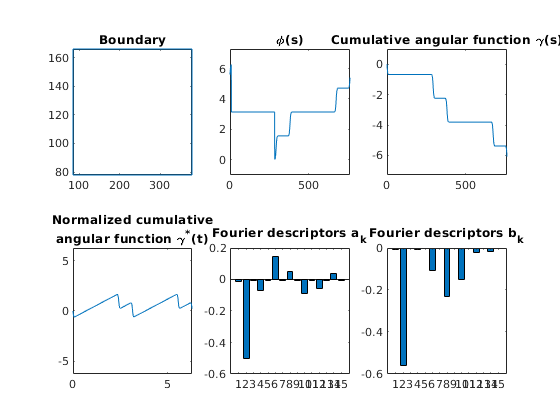

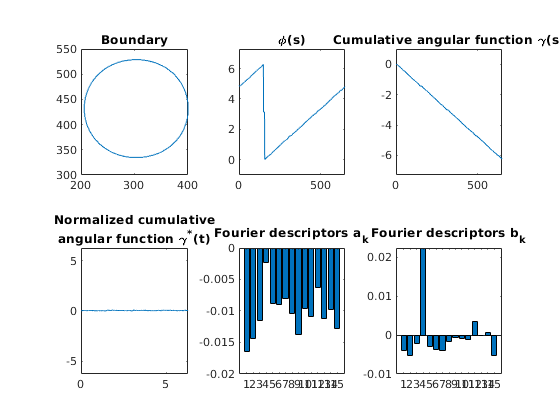

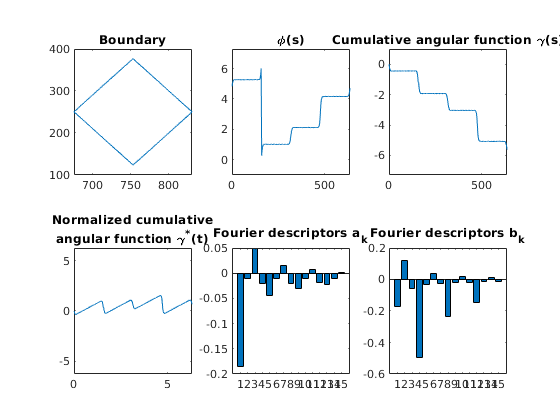

% Extract the boundary in Matlab
im = imread('geom.png');
% imshow(im)
% Image binarization
if (~islogical(im))
    if (ndims(im)>2) % Convert image to grayscale, if it is not already in this format
        im = rgb2gray(im);
    end
    level=graythresh(im); % Getting gray treshold of image using Otsu's binarization technique
    BW = im2bw(im,level);
else % If image is already grayscaled, don't modify it
    BW = im;
end
% Invert the colors of the image, such that the objects of interest are
% white
BW = ~BW;

% figure, imshow(BW)
% Image segmentation (in case multiple objects are present)
[B, L, N] = bwboundaries(BW, 'noholes');
% N - objects found in image
% B - structure containing the boundary of each object
% L - label matrix

n = 15; % Number of Fourier coefficients to use
% Display the boundary of each object in the image 
for (k=1:N)
    X = B{k}(:,2);
    Y = B{k}(:,1);
    contour = [X'; Y'];
    angularFunctionDescriptors(contour, n);
end

## Exercise 2

I have uploaded an image containing only a rectangle in Matlab. After boundary extraction, I have calculated and plotted the distance from each boundary point to the center of mass. This gave a periodic function.

The period of the function r is equal to half the perimeter of the rectangle. For similarity checking between the function r(j) given by this rectangle and some other function s(j), given by another shape, we must first normalize the two functions, to bring them to the same scale, and then compute the integral of the difference between the two functions. We must perform this operation multiple times, for multiple offsets between the two functions. So, in fact, we may use the convolution of the two normalized functions with more succes. This may give us an indication of the correlation between the shapes that have generated those functions.

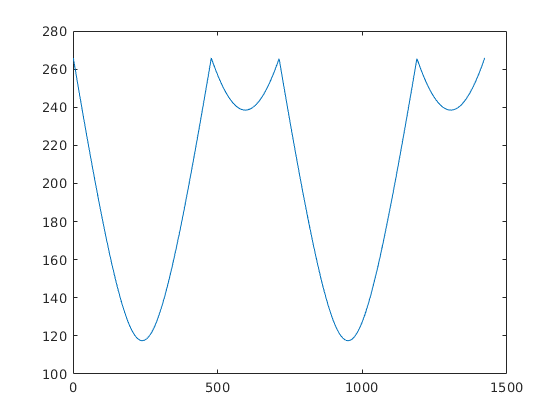

% Extract the boundary in Matlab
im = imread('rectang.png');
% imshow(im)
% Image binarization
if (~islogical(im))
    if (ndims(im)>2) % Convert image to grayscale, if it is not already in this format
        im = rgb2gray(im);
    end
    level=graythresh(im); % Getting gray treshold of image using Otsu's binarization technique
    BW = im2bw(im,level);
else % If image is already grayscaled, don't modify it
    BW = im;
end
% Invert the colors of the image, such that the objects of interest are
% white
BW = ~BW;

% figure, imshow(BW)
% Image segmentation (in case multiple objects are present)
[B, L, N] = bwboundaries(BW, 'noholes');
% N - objects found in image
% B - structure containing the boundary of each object
% L - label matrix

n = 30;
% Take every shape in the image (only the rectangle, in this case)
for (k=1:N)
    % Take the X and Y collection of points that describe the shape
    X = B{1}(:,2);
    Y = B{1}(:,1);
    
    % Find the coordinates of the center of mass of the shape
    stats = regionprops(L, 'Centroid');
    coordinates = stats(1).Centroid;
    xc = coordinates(1);
    yc = coordinates(2);
    
    % Calculate the distance from the center of mass to the boundary points
    rj = sqrt((X-xc).^2 + (Y-yc).^2);
    figure;
    plot(rj)
%     contour = [X';Y'];
%     ellipticFourierDescriptors(contour, n);
end

## Exercise 3

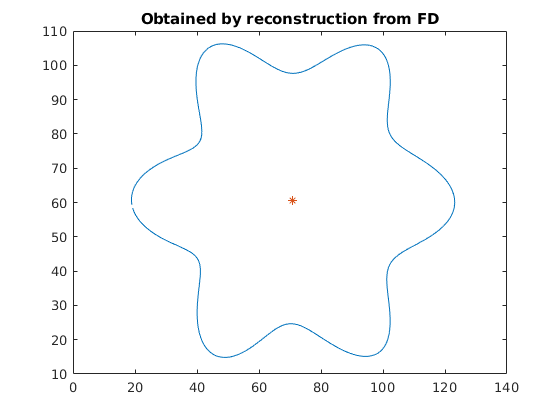

% Boundary reconstruction based on the Fourier series coefficients
m = 327; nc = 7;
T = m;
w = 2*pi/T;

ax1 = -44.2; ax2 = 0.6; ax3 = 0.7; ax4 = -0.4; ax5 = -4.8; ax6 = -.01; ax7 = -3.7;
bx1 = 1.2; bx2 = 0.1; bx3 = -.03; bx4 = -0.2; bx5 = 0.5; bx6 = 0.1; bx7 = 0.9;
ay1 = -1.2; ay2 = -0.1; ay3 = 0.1; ay4 = 0.2; ay5 = 0.6; ay6 = -0.3; ay7 = -0.6;
by1 = -43.8; by2 = 0.8; by3 = 0.1; by4 = 0.4; by5 = 3.7; by6 = -0.6; by7 = -3.6;

ax = [ax1 ax2 ax3 ax4 ax5 ax6 ax7];
ay = [ay1 ay2 ay3 ay4 ay5 ay6 ay7];
bx = [bx1 bx2 bx3 bx4 bx5 bx6 bx7];
by = [by1 by2 by3 by4 by5 by6 by7];

ax0 = 141.6;
ay0 = 121.3;

for n = 1:m
    X2(n) = ax0/2;
    Y2(n) = ay0/2;
    for k = 1:nc
        X2(n) = X2(n) + ax(k)*cos(k*w*n)+bx(k)*sin(k*w*n);
        Y2(n) = Y2(n) + ay(k)*cos(k*w*n)+by(k)*sin(k*w*n);
    end
end

curve = [X2; Y2];
plot(curve(1,:), curve(2,:)); hold on; plot(ax0/2, ay0/2, '*'), title('Obtained by reconstruction from FD')

## **Functions for Finding the Fourier Descriptors**

**Curvature function**

function angularFunctionDescriptors(curve, nc)

% Extract points and compute the curve
X=curve(1,:);
Y=curve(2,:);
m=length(X);
figure, subplot(2,3,1);
plot(X,Y);
title('Boundary');

% Compute the curve length
S = zeros(1,m);
S(1) = sqrt( (X(1)-X(m))^2 + (Y(1)-Y(m))^2); % Compute the distance between first and last point
for i=2:m
    % Compute the distance between two succesive points and add it to the
    % vector of already calculated distances
    S(i) = S(i-1) + sqrt( (X(i)-X(i-1))^2 + (Y(i)-Y(i-1))^2); 
end
L=S(m); % L - perimeter length

% Computation of the angular function
wnd = 10; A = zeros(1,m);

for i = 1:m
    % averaging the pixel positoins on a window of size wnd in order to
    % reduce noise
    x1 = 0; x2 = 0;
    y1 = 0; y2 = 0;
    for j=1:wnd
        pa=i-j; pb=i+j;
        if (pa<1)
            pa=m+pa;
        end
        if (pb>m)
            pb=pb-m;
        end
        x1=x1+X(pa); x2=x2+X(pb);
        y1=y1+Y(pa); y2=y2+Y(pb);
    end
    x1=x1/wnd; x2=x2/wnd;
    y1=y1/wnd; y2=y2/wnd;
    
    % Compute the angular function at the boundary point i
    dx=x2-x1; dy=y2-y1;
    
    if(dx==0) 
        dx=.00001;        
    end
    
    if((dx>0) && (dy>0))
        A(i)=atan(dy/dx);
    elseif ((dx>0) && (dy<0))
        A(i)=atan(dy/dx)+2*pi;
    else 
        A(i)=atan(dy/dx)+pi;
    end 
end
subplot(2,3,2); plot(S, A);
axis([0,S(m),-1,2*pi+1]); title('\phi(s)')

% Compute the cumulative angular function
G = zeros(1,m);
for i = 2:m
    dA = A(i)-A(i-1);
    d = min(abs(dA), abs(abs(dA)-2*pi));
    if(d>0.5)
        G(i)=G(i-1);
    elseif(dA < -pi)
        G(i) = G(i-1) - (dA + 2*pi);
    elseif(dA > pi)
        G(i) = G(i-1) - (dA - 2*pi);
    else
        G(i) = G(i-1) - dA;
    end
end
subplot(2,3,3); plot(S,G); axis([0,S(m), -2*pi-1,1])
title('Cumulative angular function \gamma(s)')

t = (2*pi*S)/L;
F = G + t;
subplot(2,3,4);
plot(t, F); axis([0, 2*pi, -2*pi, 2*pi]);
title(["Normalized cumulative", "angular function \gamma^*(t)"])

% COmputation of the Fourier descriptors
a = zeros(1, nc); b= zeros(1,nc);
for k = 1:nc
    a(k) = a(k) + G(1)*(S(1))*cos(2*pi*k*S(1)/L);
    b(k) = b(k) + G(1)*(S(1))*sin(2*pi*k*S(1)/L);
    for i = 2:m
        a(k) = a(k) + G(i)*(S(i)-S(i-1))*cos(2*pi*k*S(i)/L);
        b(k) = b(k) + G(i)*(S(i)-S(i-1))*sin(2*pi*k*S(i)/L);
    end
    a(k) = a(k)*(2/L);
    b(k) = b(k)*(2/L)-2/k;
end
subplot(2,3,5); bar(a);
title("Fourier descriptors a_k")
subplot(2,3,6); bar(b);
title("Fourier descriptors b_k")
end

**Eliptic fourier descriptors**

function ellipticFourierDescriptors(c,nc)

X = c(1,:);
Y = c(2,:);
m = length(X);
T = m;
w = 2*pi/T;
tau = T/m;


% Coefficient computation
ax=[];
bx=[];
for k=1:nc
    ax(k) = 0;
    bx(k) = 0;
    for i=1:m
        ax(k) = ax(k) + X(i)*cos(k*w*i*tau);
        bx(k) = bx(k) + X(i)*sin(k*w*i*tau);
    end
end

ax = (2/m)*ax; bx = (2/m)*bx; ax0 = 2/m*sum(X); bx0 = 0;

ay=[];
by=[];
for k=1:nc
    ay(k) = 0; by(k) = 0;
    for i=1:m
        ay(k) = ay(k) + Y(i)*cos(k*w*i*tau);
        by(k) = by(k) + Y(i)*sin(k*w*i*tau);
    end
end

ay = (2/m)*ay; by = (2/m)*by; ay0 = 2/m*sum(Y); by0 = 0;

% Boundary reconstruction based on the Fourier series coefficients

for n = 1:m
    X2(n) = ax0/2;
    Y2(n) = ay0/2;
    for k = 1:nc
        X2(n) = X2(n) + ax(k)*cos(k*w*n)+bx(k)*sin(k*w*n);
        Y2(n) = Y2(n) + ay(k)*cos(k*w*n)+by(k)*sin(k*w*n);
    end
end

c2 = [X2; Y2];

figure
subplot(3,2,1), plot(c(1,:), c(2,:)); title("Boundary")
subplot(3,2,2), plot(c2(1,:), c2(2,:)); hold on; plot(ax0/2, ay0/2,'*'); title("Reconstructed boundary based on FD");
subplot(3,2,3), bar(ax), title('a_x')
subplot(3,2,4), bar(bx), title('b_x')
subplot(3,2,5), bar(ay), title('a_y')
subplot(3,2,6), bar(by), title('b_y')

end